## TOPIC 16: Working with text, pt 2

ENGR105, 10/27/20

#### Reminder: working with text

The ability to work with and manipulate text is important in many different applications: both those that *explicitly* deal with text data (e.g. studying genomic data) and those that involve numerical data but have some *text identifier* (e.g. batch processing of data files, images, etc.).

**Loading text.**. `importdata() `reads in each line of text as a cell array index.

txt1 = importdata('TextData.txt');
size(txt1)

ans =     85     1


`fileread() `reads a text file as one long character array.

%read as one long character array
txt2 = fileread('TextData.txt');
size(txt2)

ans =            1        3630


**Note**: unless explicitly specified (HW 8), you should use which ever works better for a given situation.

**Character arrays can be read from cells in a cell array**. 

% Read the 39th line as a character array
c = txt1{39}

c = 'Only got twenty dollars in my pocket'

Character vectors and arrays can be** indexed similarly as numeric arrays** and operated upon by many common array functions

% Using vector indexing to retrieve sub arrays of characters from the "c"
t1 = c(1:5)

t1 = 'Only '

% Concatenate array
t2 = [t1,' , ',t1]

t2 = 'Only  , Only '

Character arrays can use** logical indexing**.

% Create a text array without spaces
t2 = t2(t2 ~= ' ')

t2 = 'Only,Only'

**Character and string functions**. There are many high level functions to operate on character arrays and strings 

- `isletter()`: returns logical array indicating whether a particular character is a **letter** or not (**true**: that character is a letter).

c = txt1(39)

c = 1×1 cell array
    {'Only got twenty dollars in my pocket'}


% Logical array indicating positions that are letters
v1 = isletter(c)

v1 = logical
   0


- `isspace()`: returns logical array indicating whether a particular character is a **space** or not (**true**: that character is a space).

% Logical array indicating positions that are spaces
v2 = isspace(c)

v2 = logical
   0


- Functions to change the **case** of a character sting

% Convert all to upper case
sU = upper(c)

sU = 1×1 cell array
    {'ONLY GOT TWENTY DOLLARS IN MY POCKET'}


% Convert all to lower case
sL = lower(c)

sL = 1×1 cell array
    {'only got twenty dollars in my pocket'}


- **Finding** a piece of text inside a character array

% Create index at which word "dollars" appears
ind = strfind(c,'twenty') 

ind = 1×1 cell array
    {[10]}


ind = strfind(c,'t')

ind = 1×1 cell array
    {1×4 double}


Many more functions may be found here:

[https://www.mathworks.com/help/matlab/characters-and-strings.html](https://www.mathworks.com/help/matlab/characters-and-strings.html) 

#### Practice Problem: analyzing song lyrics

Consider the data in `txt1`, imported above. How many words are in the 46-th line? What is the average word length?

% Step 1: Read the 46th line 
c1 = txt1{46}

c1 = 'What you know about rockin' a wolf on your noggin?'


%Step 2: Remove punctiation
c1 = c1(isletter(c1)|isspace(c1))

c1 = 'What you know about rockin a wolf on your noggin'

%Step 3: Isolate each word
% Step 3a: add a space to front and back of text
c1 = [' ', c1, ' ']

c1 = ' What you know about rockin a wolf on your noggin '

% Step 3b: Determine where spaces are
spaces = strfind(c1, ' ')

spaces =      1     6    10    15    21    28    30    35    38    43    50


% Step 3c: Store each word in cell array. note: if we have n spaces, then
% we will have n - 1 words.
myCell = cell(1,length(spaces)-1); % Preallocate cell array

% loop through all spaces to store words
for k = 1:length(myCell)
    myCell{k} = c1(spaces(k)+1:spaces(k+1)-1);
end
disp(myCell)

  Columns 1 through 7

    {'What'}    {'you'}    {'know'}    {'about'}    {'rockin'}    {'a'}    {'wolf'}

  Columns 8 through 10

    {'on'}    {'your'}    {'noggin'}



Q1: how many words are there?

numWords = numel(myCell)

numWords = 10

Q2: What is the average word length?

numLetters = 0;
%Loop through all words, add number of letters
for k = 1:numWords
    numLetters = numLetters + length(myCell{k})
end

numLetters = 4

numLetters = 7

numLetters = 11

numLetters = 16

numLetters = 22

numLetters = 23

numLetters = 27

numLetters = 29

numLetters = 33

numLetters = 39

avgLength = numLetters/numWords

avgLength = 3.9000

Q3: in the above case, we analyzed one *line* of text. How could we modify this to analyze *all* of the lines of text in the file?

#### Practice Problem: the central dogma of molecular biology

The **central dogma of molecular biology** is an explanation of the genetic flow of information in a biological system, often stated as "DNA makes RNA, and RNA makes protein." *Depicted visually (from *[wikipedia](https://en.wikipedia.org/wiki/Protein_production)*):*

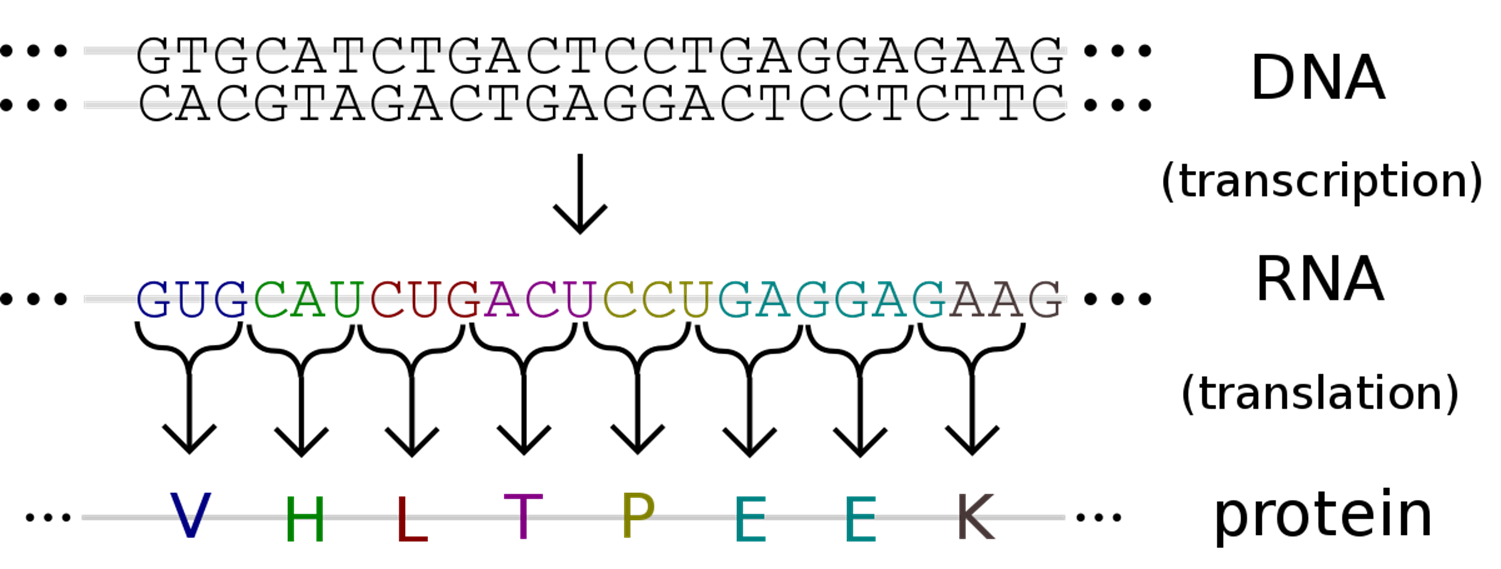

*Key terms for this problem:*

- **DNA**: the "genetic blueprint" for life. Strands of DNA are biopolymers consisting of a sequence of monomers, known as nucleotides. Each nucleotide consists of one base (cytosine [**C**], guanine [**G**], adenine [**A**] or thymine [**T**]), a sugar (deoxyribose), and a phosphate group. **Information is stored in the sequence of bases**, and DNA sequences are represented as a sequence of A, T, C, and G. Example: `TCTTGTTTTATTG`

- **mRNA**: the "instructions copied from DNA" dictating how to construct a protein. Like DNA, strands of RNA are biopolymers consisting of a sequence of nucleotide monomers. In this case, each nucleotide consists of one base (cytosine [**C**], guanine [**G**], adenine [**A**] or uracil [**U**]), a sugar (ribose), and a phosphate group. An mRNA strand is** produced from its DNA template**, with all bases matching except with uracils replacing thymines. Information is stored in the sequence of bases, and mRNA sequences are represented as a sequence of A, U, C, and G. Example corresponding to the above: `UCUUGUUUUAUUG`

- **Protein**: the "functional units" produced from an mRNA template. Encoded from mRNA, proteins are biopolymers that consist of a sequence of amino acid monomers. There are 20 naturally occuring amino acids.

- **Codon**: sequence of three bases that specify which amino acid will be added next to *a protein that is being constructed*.

% List of codons. Note the use of importdata()
codon_list = importdata('codonList.txt');
disp(codon_list)

    {'TTT,Phenylalanine,F'}
    {'TTC,Phenylalanine,F'}
    {'TTA,Leucine,L'      }
    {'TTG,Leucine,L'      }
    {'TCT,Serine,S'       }
    {'TCC,Serine,S'       }
    {'TCA,Serine,S'       }
    {'TCG,Serine,S'       }
    {'TAT,Tyrosine,Y'     }
    {'TAC,Tyrosine,Y'     }
    {'TAA,Stop,X'         }
    {'TAG,Stop,X'         }
    {'TGT,Cysteine,C'     }
    {'TGC,Cysteine,C'     }
    {'TGA,Stop,X'         }
    {'TGG,Tryptophan,W'   }
    {'CTT,Leucine,L'      }
    {'CTC,Leucine,L'      }
    {'CTA,Leucine,L'      }
    {'CTG,Leucine,L'      }
    {'CCT,Proline,P'      }
    {'CCC,Proline,P'      }
    {'CCA,Proline,P'      }
    {'CCG,Proline,P'      }
    {'CAT,Histidine,H'    }
    {'CAC,Histidine,H'    }
    {'CAA,Glutamine,Q'    }
    {'CAG,Glutamine,Q'    }
    {'CGT,Arginine,R'     }
    {'CGC,Arginine,R'     }
    {'CGA,Arginine,R'     }
    {'CGG,Arginine,R'     }
    {'ATT,Isoleucine,I'   }
    {'ATC,Isoleucine,I'   }
    {'ATA,Isoleucine,I'   }
    {'ATG,Methionine

**Important notes: **

- Genes occur in sets of three bases. One codon (three bases) specifies an amino acid.

- Methionine (DNA base sequence `ATG`) is nearly always the "Start" codon, indicating the start of a sequence for a gene.

- There are three common "Stop" codons that indicate where a gene sequence stops: DNA base sequences `TAA`, `TAG`, `TGA`.

- We are representing these biomolecules as text. Remember that these correspond to* different chemical structures*.

*Short summary:*

- DNA specifies mRNA, which encodes the protein to be made.

- DNA/mRNA can be represented as text - either ATCG or AUCG

- Protein can be represented as text - a string of one of twenty letters.

In this problem, we will analyze this flow of biological information describing the **"spike"** protein on the membrane of **severe acute respiratory syndrome coronavirus 2 (SARS-CoV-2)**.SARS-CoV-2 is an enveloped, *positive-sense*, single-stranded RNA virus that causes coronavirus disease 2019 (COVID-19). Virus particles include the RNA genetic material and structural proteins needed for invasion of host cells. Once inside the cell the infecting RNA is used to encode structural proteins that make up virus particles, nonstructural proteins that direct virus assembly, transcription, replication and host control and accessory proteins whose function has not been determined. 

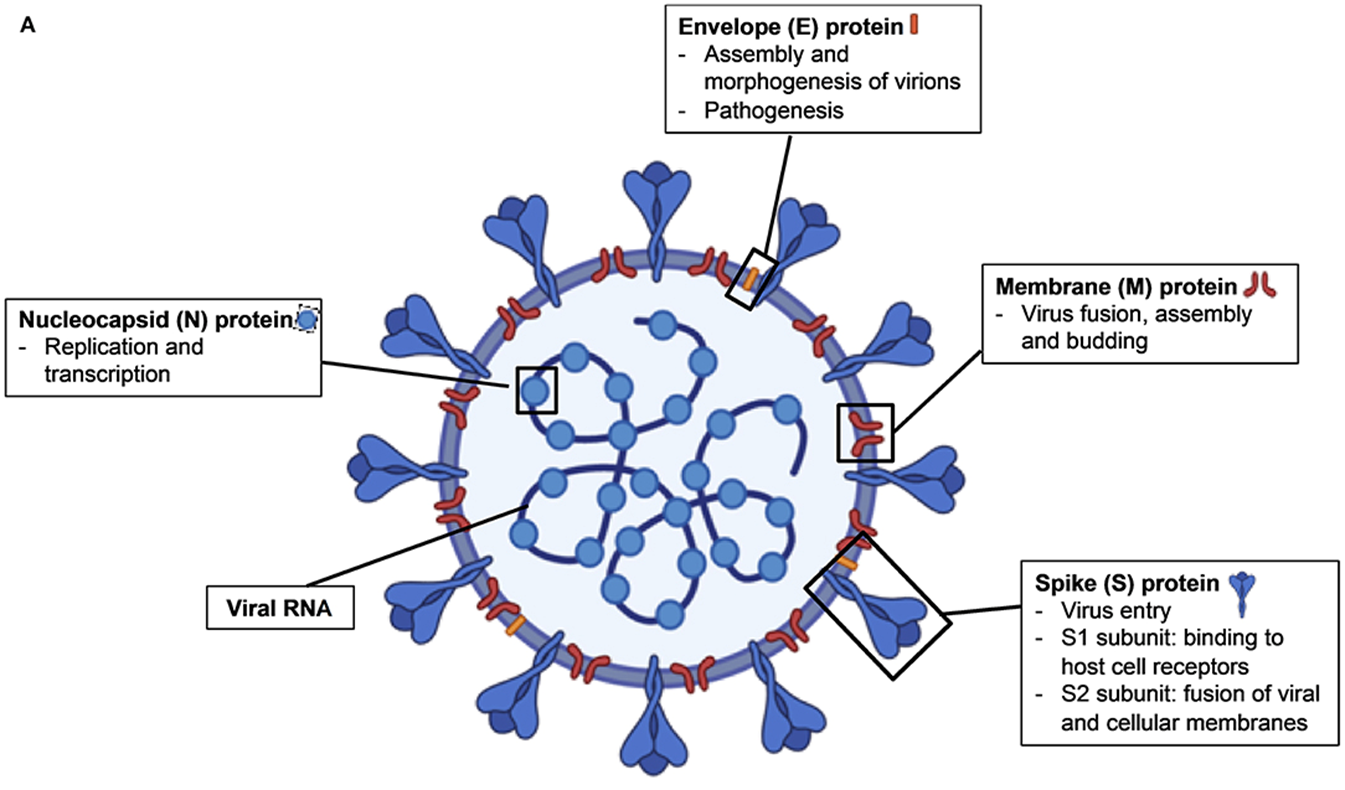

***Source DOI: ***[***10.3389/fimmu.2020.00879***](https://www.frontiersin.org/articles/10.3389/fimmu.2020.00879/full)

The structural proteins of SARS-CoV-2 include the envelope protein, **spike or surface glycoprotein**, membrane protein and the nucleocapsid protein. **The spike glycoprotein is found on the outside of the virus particle and gives coronavirus viruses their crown-like appearance. This glycoprotein mediates attachment of the virus particle and entry into the host cell.** This protein is an *important target* for vaccine development, antibody therapies and diagnostic antigen-based tests.

***Key resources and references:***

- Review of SARS-CoV-2 and COVID-19: [https://www.nature.com/articles/s41579-020-00459-7](https://www.nature.com/articles/s41579-020-00459-7)

- Genomic information (Wuhan-Hu-1): [https://www.ncbi.nlm.nih.gov/nuccore/NC_045512](https://www.ncbi.nlm.nih.gov/nuccore/NC_045512)

**Problem statement**

Given a DNA primer (a short sequence of DNA representing the first few bases of a given gene) for the spike glycoprotein and the genome of SARS-CoV-2, answer the following questions:

**Question 1:** how many bases are in the SARS-CoV-2 genome?

**Question 2:** how many of *each* base appear in the genome?

**Question 3:** given a primer, what is the DNA sequence for the spike glycoprotein? How many bases long is it?

**Question 4:** what is the mRNA transcript of the spike protein?

**Question 5:** What is the amino acid sequence of the spike protein?

**Question 6:** How many of each amino acid are in the spike protein?

**First thing to do: organize information that is provided**

*SARS-CoV-2 genome:*

% Import genomic information as one long character array.
% NOTE: difference from importdata()
sarsCov2_genome = fileread('sarsCov2_genome.txt');  % Read text file
sarsCov2_genome = sarsCov2_genome(isletter(sarsCov2_genome));   % remove spaces and commas
sarsCov2_genome = upper(sarsCov2_genome);   % Convert to upper case
disp(sarsCov2_genome)

ATTAAAGGTTTATACCTTCCCAGGTAACAAACCAACCAACTTTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGGCTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCGTCTATCTTCTGCAGGCTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTTTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGTCTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGCGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCGGATGCTCGAACTGCACCTCATGGTCATGTTATGGTTGAGCTGGTAGCAGAACTCGAAGGCATTCAGTACGGTCGTAGTGGTGAGACACTTGGTGTCCTTGTCCCTCATGTGGGCGAAATACCAGTGGCTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCCGATCTAAAGTCATTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTTACCCGTGAACTCATGCGTGAGCTTAACGGAGGGGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCACGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAGAGGGGTGTATACTGCTGCCGTGAACATGAGCATGAAATTGCTTGGTACACGGAACGTTCT

*Spike protein primer:*

% DNA sequence that you know starts the gene
spike_FWprimer = 'ATGTTTGTTTTTCTTGTTTTATTG';

*Codon information - reorganize into a three column cell array for easier accessibility:*

% NOTE: one cell in codon_list (imported above) is a line of information
% containing 1) the nucleotides, the name, and abbreviation for
% each amino acid. We want each of these three items in a separate column
codon_list = importdata('codonList.txt');
disp(codon_list);

    {'TTT,Phenylalanine,F'}
    {'TTC,Phenylalanine,F'}
    {'TTA,Leucine,L'      }
    {'TTG,Leucine,L'      }
    {'TCT,Serine,S'       }
    {'TCC,Serine,S'       }
    {'TCA,Serine,S'       }
    {'TCG,Serine,S'       }
    {'TAT,Tyrosine,Y'     }
    {'TAC,Tyrosine,Y'     }
    {'TAA,Stop,X'         }
    {'TAG,Stop,X'         }
    {'TGT,Cysteine,C'     }
    {'TGC,Cysteine,C'     }
    {'TGA,Stop,X'         }
    {'TGG,Tryptophan,W'   }
    {'CTT,Leucine,L'      }
    {'CTC,Leucine,L'      }
    {'CTA,Leucine,L'      }
    {'CTG,Leucine,L'      }
    {'CCT,Proline,P'      }
    {'CCC,Proline,P'      }
    {'CCA,Proline,P'      }
    {'CCG,Proline,P'      }
    {'CAT,Histidine,H'    }
    {'CAC,Histidine,H'    }
    {'CAA,Glutamine,Q'    }
    {'CAG,Glutamine,Q'    }
    {'CGT,Arginine,R'     }
    {'CGC,Arginine,R'     }
    {'CGA,Arginine,R'     }
    {'CGG,Arginine,R'     }
    {'ATT,Isoleucine,I'   }
    {'ATC,Isoleucine,I'   }
    {'ATA,Isoleucine,I'   }
    {'ATG,Methionine

codons = cell(length(codon_list),3);

%process each line and seperate the elements 

tempCodon = codon_list{k}

tempCodon = 'TAC,Tyrosine,Y'

commaInd = strfind(tempCodon, ',')

commaInd =      4    13


for k = 1:length(codon_list)
    %First cell codon ATCG
    codons{k,1} = tempCodon(1:commaInd(1)-1);
    %second cell: name of amino acid
    codons{k,2} = tempCodon(1:commaInd(2)-1);
    %third cell: First cell codon ATCG
    codons{k,1} = tempCodon(commaInd(2)+1:end);

end 

**Note**: the codons listed are given in terms of *DNA bases*.

**Question 1:** how many bases are in the SARS-CoV-2 genome?

% Number of bases equals number of elements in the character vector
numBases = length(sarsCov2_genome)

numBases = 29903

**Question 2:** how many of *each* base appear in the genome?

**Note**: for this problem we consider only one strand.

% Step 1: Determine how many of each base are in the genome
base_A = length(sarsCov2_genome(sarsCov2_genome == 'A'))

base_A = 8954

base_T = length(sarsCov2_genome(sarsCov2_genome == 'T'))

base_T = 9594

base_C = length(sarsCov2_genome(sarsCov2_genome == 'C'))

base_C = 5492

base_G = length(sarsCov2_genome(sarsCov2_genome == 'G'))

base_G = 5863


% Step 2: Plotting 
% Create cell array containing each x label
xval = {'A', 'T', 'C', 'G'}

xval = 1×4 cell array
    {'A'}    {'T'}    {'C'}    {'G'}


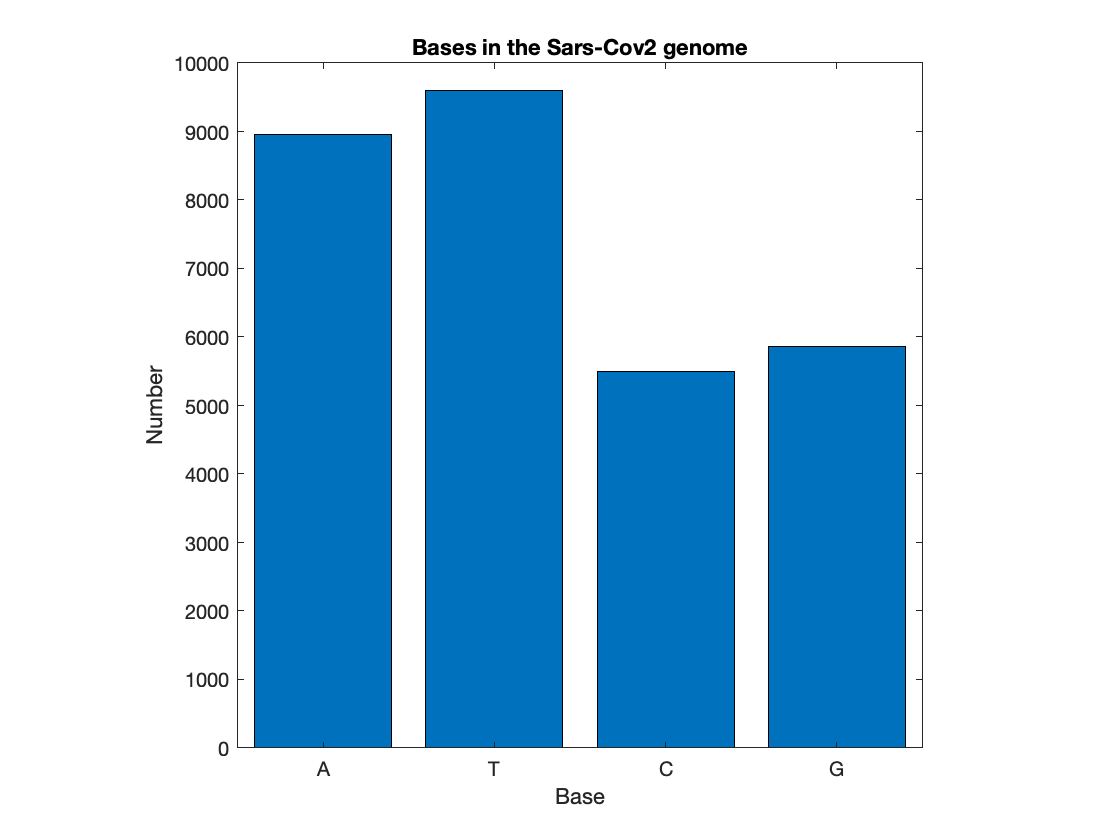

%Convert cell array to categorical and then reorder to be in the same order
xval2 = categorical(xval);
xval2 = reordercats(xval2, xval)';

% Make bar graph 
bar(xval2, [base_A, base_T, base_C, base_G]);
title('Bases in the Sars-Cov2 genome')
axis square
ylabel('Number');
xlabel('Base');

**Question 3:** given a primer, what is the DNA sequence for the spike glycoprotein? How many bases long is it?

#### Writing text data to a file

- Simple: Write a **cell array** to a **delimitted file** using `writecell`. Any delimiter may be used but comma-delimitted is the default.

% % Write codons to a text file
% writecell(codons,'myCodonFile.txt');

- More involved: use built-in MATLAB **file manipulation commands**: `fopen`, `fprintf`, `fclose`

% % Create and open a new file with specified name
% fileID = fopen('S_ProteinSequence.txt','w');
% % Write character array to file
% fprintf(fileID,spike_Protein);
% % Close file so that it can be read elsewhere
% fclose(fileID);

Unrecognized function or variable 'spike_Protein'.